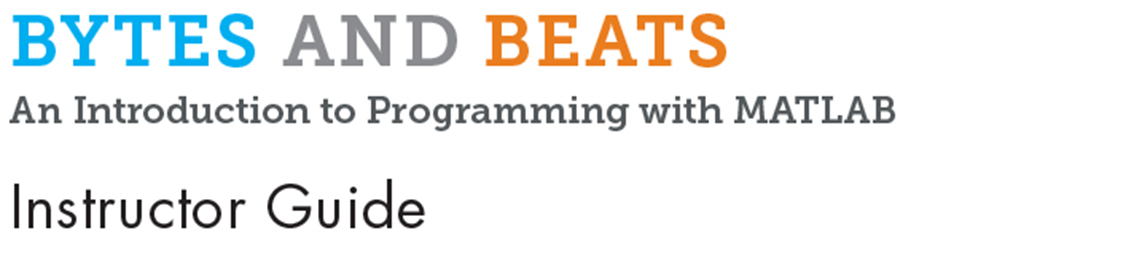

# Module 9: Understanding Loops

**Prerequisite Domain Knowledge:** *Module 8*, Functions

**Expected Completion Time: **50 minutes

## Using a 'for' loop

*Expected Duration: 30 minutes*

### Learning Objectives

- Identify the need for a loop 

- Learn to create a for-loop

### Motivation

The students have created their musical pieces. In this script, they most likely have repetitive function calls with different inputs. 

Recap the Happy Birthday song and open the solution script. Here is the original code for playing just the first line of the song:

As you can see, the `'sineSound'`and `'pause'` function calls are repeated for each tone. This repetition can be eliminated with a combination of vectors and `for` loops.

Spend time on this section as loops are an important programming concept.

### Materials

- MATLAB®

### Solution

 
open Happy_Birthday_for_solution.mlx

### Steps:

Introduce the activity using the motivation above. You could ask questions such as:

- Did you get tired of typing or copying and pasting the same lines of code repeatedly?

- Introduce the solution - that is to use `for `loops.

- A `for` loop repeats certain lines of code for a certain set of conditions. 

Have the students open a Live Script to practice loops by using the below command in the **Command Window:**

 
open CreatingLoops.mlx

Type the basic syntax for a `for `loop as below. 

 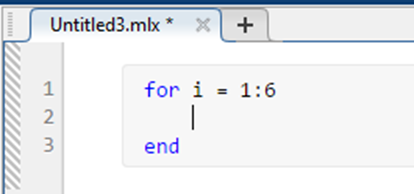

Notice that MATLAB automatically adds the `end` statement and indents the lines inside the `for` loop to make it is easier to see what is inside and outside the loop.

- Tell the students that this loop executes the lines between the `for` and the `end` statements 6 times. The variable `i` is the counter. Every time the lines inside get executed, the values of `i` increase by 1. Once its value reaches 6, the loop ends and the lines after `end` are executed.

Let the students verify this by adding lines to display the value of` i` inside the loop and a message after the loop. 

  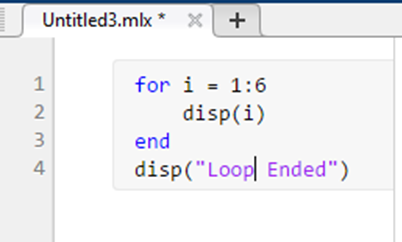

Run the code and you should see the output as below:

 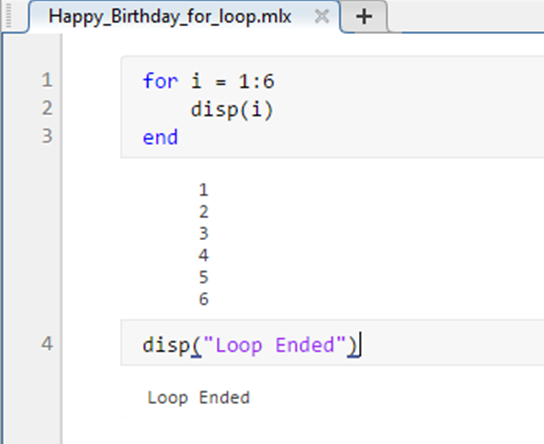

The students will now modify this code to play the Happy Birthday song. They will first need to find the number of repetitions. Have the students count the number of times they use `sineSound `for the first line of Happy Birthday song, and that becomes the length of the loop. 

The answer is 6, since there are 6 notes.

So, the `for `statement remains the same. It goes up to 6.

Ask the students what function calls they need to repeat. Type these lines between the `for`and `end` statements.

For now, they will call the '`sineSound'`function with the first note to the song i.e. G4 and pause for 0.2 seconds. Remember to assign frequency value to variable `G4` before the loop.

 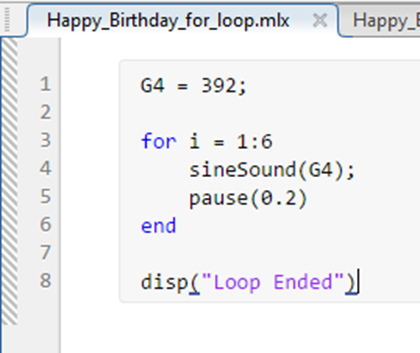

Ask them what this loop will do.

- It will play the frequency G4 6 times.

But we want to play a different frequency each time. How do we do that?

- We can store all the note frequencies in a numeric vector and use the `for `loop counter to ***index ***into this vector. Have the students follow along as you add these lines to the code and discuss.

We create variables for unique frequencies occurring in the first line of the song. 

Next, the `freq`vector is used to store the frequencies in order of the first line.

Finally, the counter `i` is used to index into `freq`vector inside the `for` loop to play each note one after the other.

  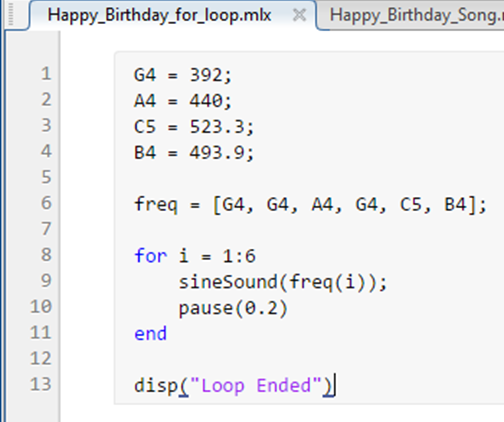

Spend some time to ensure that students understand what is happening.

- In the 1st run `i` =1, so `freq(i)`= G4, which holds the value 392.

- 2nd  run: *i* = 2, so `freq(i)`= G4 again.

- 3rd run: *i *= 3, so `freq(i)` = A4, which holds the value 440.

And so on until 6. 

- Ask the students to create a `for `loop for the entire Happy Birthday song. The `for`loop would need to run from 1 to 25. The students would also need to complete the numeric vector `freq `for all the 25 notes of the song. 

- Finally, having different durations for each note will make the tune closer to the real song. Ask the students how they might do that. They should realize that it can be done in an analogous way as we did frequencies:

- Create a numeric vector containing the time durations of the notes (say, `t_dur`).  Now, the constant value of 0.2 can be replaced by `t_dur(i). `The `t_dur `should be equal to the pause duration or the notes will overlap. 

- You can help the students by giving them a tip about the durations: First two notes of each line can be 0.4 and 0.2 seconds long, respectively. Last note can be 0.8 seconds long and the remaining can be 0.6 seconds each.

Give them some time to play with this.

- If time permits, allow the students to play with these ideas in their scripts.

- Add chords by making the pause duration for those notes to be 0. 

- Make the tune slower by multiplying the duration vector (p_`dur`) with a scalar greater than 1; or faster by multiplying it with a scalar between 0 and 1.

- Similarly, turn the scale (pitch) up or down by multiplying the frequency (`freq`) vector by a scalar.

- Make the pause duration and frequency duration vectors different, for more flexibility. 

- Replace the counter maximum value in the `for` statement using the `length` function for better code reusability:

Discuss: The length of our code is reduced significantly by using `for` loops. A lot of repetition was avoided by using loop and vectors.

## Practicing 'for' loops

*Expected Duration: 20 minutes*

### Learning Objectives

Some exercises for students to practice loops. They will be able to:

- Create `for` loops with a linearly increasing “counting” dummy vector.  

- Create `for` loops over a dummy vector which contains arbitrary elements.

- Use the dummy variable to index into a separate array.  

- Use the dummy variable to perform calculations.  

- Concatenate number and string using the plus (+) operator.

### Motivation

Students should now have a good understanding of loops. This activity will help reinforce the concept and practice further. 

### Materials

- MATLAB

### Steps

Explain the motivation and that there are two types of computer loops.

- Loops that repeat a certain number of times.

- Loops that repeat forever until something specific happens, (such as when a button is pressed, or a maximum score is achieved, or the user quits, and so forth)

- The first is called a `for` loop, the second is called a `while` loop. 

- We will use a `for` loop for this example.

Explain `for` loop syntax with a simple script:  

- It begins with “for” and ends with “end.”  The code inside is repeated each run through the loop.  `k `is a dummy variable we use for purposes just for the loop.  

- `k`starts at 1 and ends at 6; the loop runs 6 time

- the values of `k`are given as output each time

Slow the loop down. As computers are fast, the process happens almost instantaneously, but we can see this in slow motion if we pause the loop each time.

Do some math with `k`.  Remember that `k`= 1:6 is just a vector. It is the same as `k`= [1 2 3 4 5 6].  Let’s also do some math with `k`.

#### Optional

Initialize a variable. You can use `for `loops to repeatedly add to a variable. To do so, you must initialize the variable first.  

For example, you can use a `for `loop to multiply a number by 2, 10 times.

However, the above doesn’t make sense, as we do not know what `x` is to start off.  Therefore, initialize x before the start of the for-loop.

Convert numbers to characters.  In the ‘k-multiplied by 3’ example, we said “ k ‘multiplied by 3’ but it would be better to say the actual number, which is multiplying by three. How can we combine numbers and strings? (We will need to do this for our note array.)

Using the plus ( + ) operator with strings will combine the number two strings or a number and string to form a sentence.

The name `k`, as all variable names are, is also arbitrary. We could call it anything, for example: 

The vector [3 5 6 5 2 1] is just a vector.  It could have been defined anywhere before, as well.

Explain that the variables here are not named coincidentally. The students already have a melody vector corresponding to notes to be played. They can step through the melody vector in a `for `loop with the variable `note `being the present note to be played each time.

**Helper Functions **(do not edit)

function varargout = sineSound(varargin)

    Fs = 8000; 
    Ts = 1/Fs;
    
if nargin == 1
    freq = round(varargin{1},3);
    time = 0.2 ; 
    amp = 1;
    
elseif nargin == 2
    freq = round(varargin{1},3);
    time = round(varargin{2},3) ; 
    amp = 1;
    
elseif nargin == 3
    freq = round(varargin{1},3);
    time = round(varargin{2},3) ; 
    amp = varargin{3};
   
end

t = 0:Ts:time;
pure_sine = sin(2*pi*freq*t); 
step = 1/(length(t)/2); 
len = 1;
sine_coefficient = [(sin((pi* [0:step:len/2.0]) / (len))) ...
                        ones(1, length([len/2.0:step:len*3/2]) - 2)...
                        abs(sin((pi* [len*3/2:step:len*2.0]) / (len)))]; %#ok<*NBRAK>

env = 0.5*amp.*pure_sine.*sine_coefficient;


if nargout == 1
    varargout{1} = env';
else 
    sound(env, Fs);
end
end

© COPYRIGHT 2024 by The MathWorks®, Inc.